%% WV Eddy
%alongtrackLonLat from OceanDB
%eddyPath_track from ssh max closed contour centroid
%eddy_field is an array of eddy field in (x,y,t,ssh)
clear all

## 1. Extract tracks along the eddy path

% define domain
current_file_path = matlab.desktop.editor.getActiveFilename;
[current_dir, ~, ~] = fileparts(current_file_path);
readdir = 'E:\My Drive\AlongTrack\MyCode\backup\myCode\';
filename = 'BetaEddyOne.nc';
% Load Model
x_QG = ncread([readdir, filename], 'x'); %meters
y_QG = ncread([readdir, filename], 'y'); %meters
ssh = squeeze(ncread([readdir, filename], 'ssh')); %meter;% matrix order in x,y,z
lato = 24;

totalDays = size(ssh, 3);
eddy_time = ([1:totalDays]-1)';
x = x_QG - mean(x_QG);
y = y_QG - mean(y_QG);

eddy_field.x = x;
eddy_field.y = y;
eddy_field.t = eddy_time;
eddy_field.ssh = ssh;

%find eddy center
clearvars eddyPath
[center_xoyo,amplitude] = findEddyCentroid(x, y, ssh,'thresholdratio',0.9,'GetBoundary', false);
eddyPath.xe = center_xoyo(:,1);
eddyPath.ye = center_xoyo(:,2);

%if you want to change the eddyPath to a function handle
eddyPath_fun_t.xe = @(t) interp1(eddy_field.t, eddyPath.xe, t, 'linear', 'extrap');
eddyPath_fun_t.ye = @(t) interp1(eddy_field.t, eddyPath.ye, t, 'linear', 'extrap');

% % extract track - takes somes time bc it loads the entire track matrix

%timeo=datenum(1992,9,25)+(0:totalDays-1)';
timeo = datenum(2000, 1, 1) + eddy_time' + 90; %Initial time is also a free parameter

% Alongtrack from Jonathan (3D matrix [atd, tracknumber, cycle])
% JasonAlongTrack.filename = strcat(readdir, 'JasonAlongTrack.nc');
% JasonAlongTrack.lat = ncread(JasonAlongTrack.filename, 'lat');
% JasonAlongTrack.lon = ncread(JasonAlongTrack.filename, 'lon');
% %JML convert time to Matlab's datenum format
% JasonAlongTrack.time = ncread(JasonAlongTrack.filename, 'time') + datenum(1950, 1, 1);
% % 
% alongtrackLatLon = alongtrackFromXYDomain(JasonAlongTrack,x,y,timeo,lato=lato,lono=-40); %options: lato=24, lono=305
% save(strcat(current_dir,'\alongtrackLatLon_QG.mat'),'alongtrackLatLon')

load(strcat(current_dir,'\alongtrackLatLon_QG.mat'))

alongtrackXY = latlon2xy_centered(alongtrackLatLon);

## 2. Apply OSSE on the QGmodel

%Output: alongtrack - contains arrays of lon,lat,x,y,t,ssh of OSSE 
% apply OSSE on an eddy_field from QG model in (x,y,t)
alongtrack = subsampleOSSE(alongtrackXY,eddy_field);


## 3. Plots and Videos of OSSE

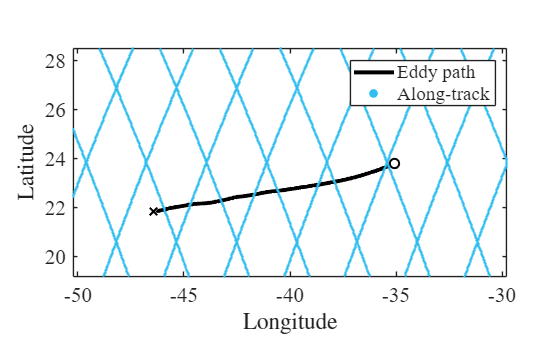

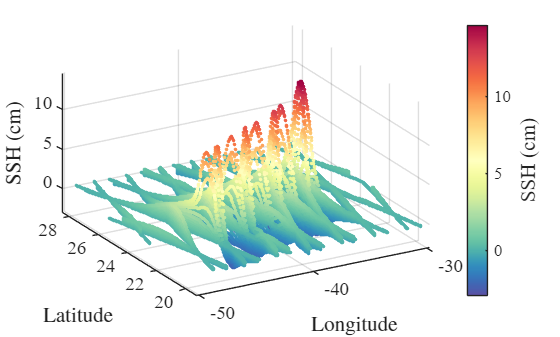

%% plot eddy path with alongtrack, and OSSE
alongtrackLatLon.ssh=alongtrack.ssh; %plotAlongtrack takes in lat lon info
plotAlongtrack(alongtrackLatLon,eddyPath);

%% make video of the propagating eddy
video_name = 'eddy_field_QGmodel';
makePropagatingVideo(x,y,eddy_time,eddy_field,video_name)


## 4. Eddy composites and plots from full field

% eddy center from eddyPath
% Full field struct
[X,Y,T] = ndgrid(1:length(eddy_field.x), 1:length(eddy_field.y), 1:length(eddy_field.t));
fullfield.x = eddy_field.x(reshape(X,[],1));
fullfield.y = eddy_field.y(reshape(Y,[],1));
fullfield.t = eddy_field.t(reshape(T,[],1))+timeo(1); % Subtract 1 to match your indexing
fullfield.ssh = reshape(eddy_field.ssh,[],1);

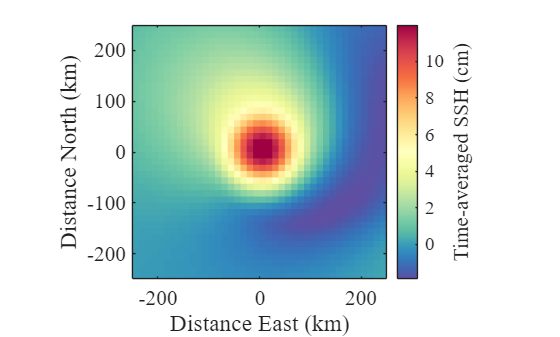

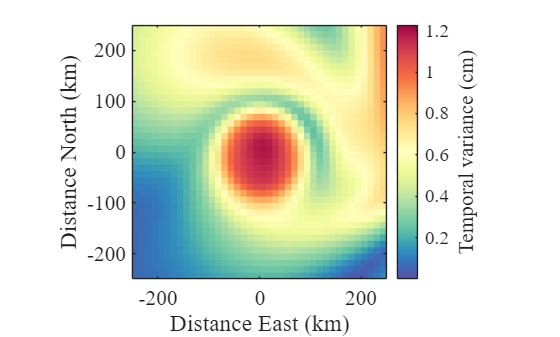

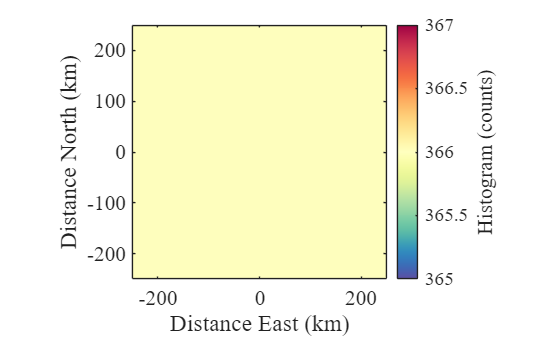

% time-averaged eddy composite from full field
[mz_xy, xmid_xy, ymid_xy, numz_xy, stdz_xy] = composite2D_grid(eddy_field,eddyPath_fun_t);% options: bin_size=12.5*1e3

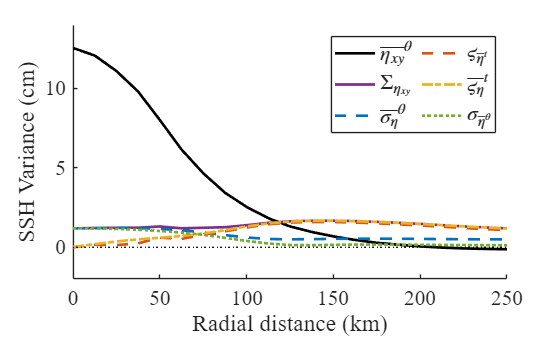

% time-averaged radial profile
[mz_r, rmid_r, numz_r, stdz_r] = radialProfile(fullfield,eddyPath_fun_t);

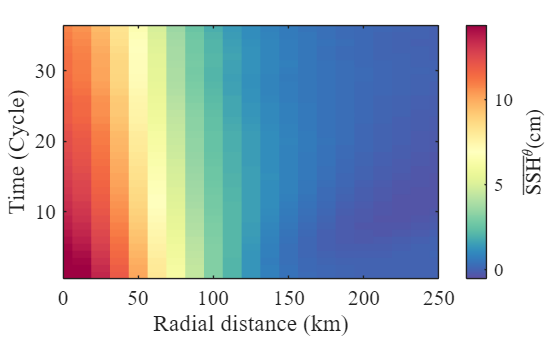

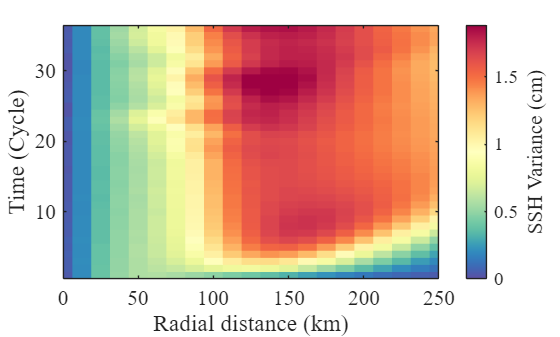

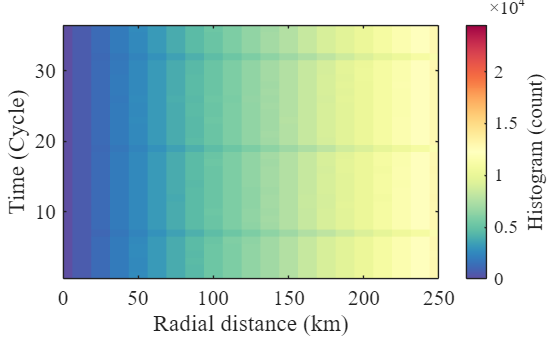

% radialProfile over time
[mz_rt, rmid_rt, tmid_rt, numz_rt, stdz_rt] = radialProfileTime(fullfield,eddyPath_fun_t);

## 4. Eddy composites

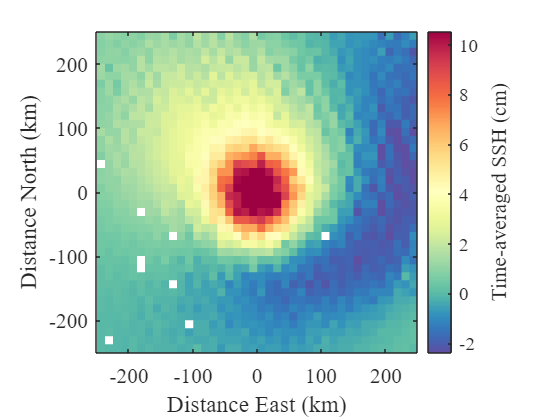

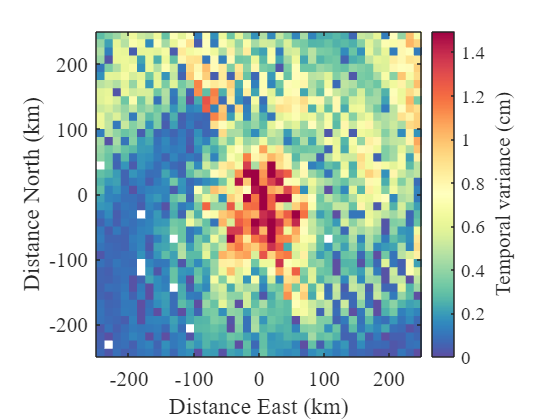

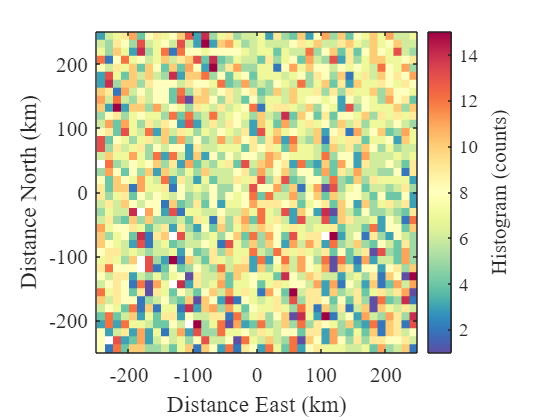

%eddy center from eddyPath_track, which is from ssh max closed contour centroid
% time-averaged eddy composite
[mz_xy, xmid_xy, ymid_xy, numz_xy, stdz_xy] = composite2D(alongtrack,eddyPath_fun_t);% options: bin_size=12.5*1e3

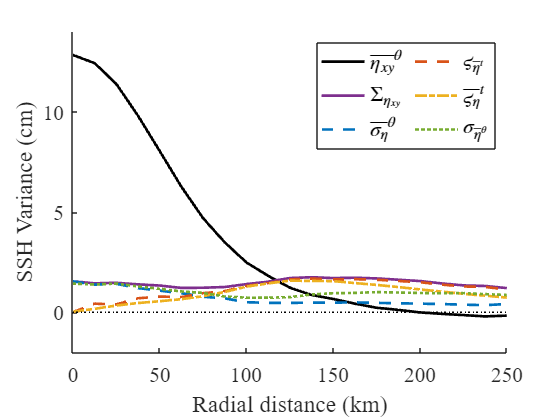

% time-averaged radial profile
[mz_r, rmid_r, numz_r, stdz_r] = radialProfile(alongtrack,eddyPath_fun_t);

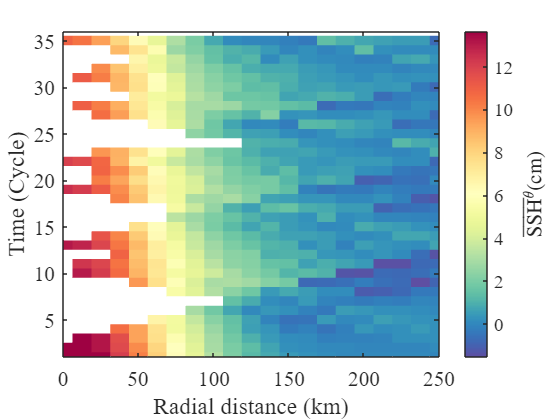

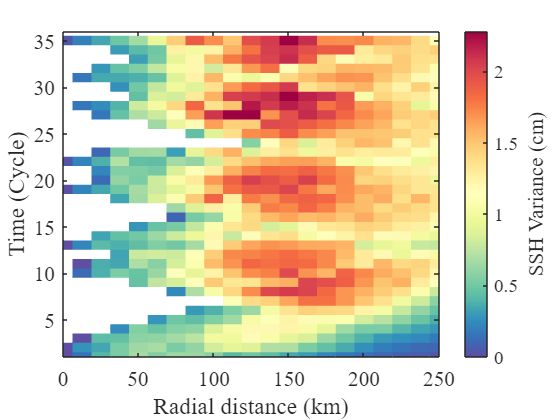

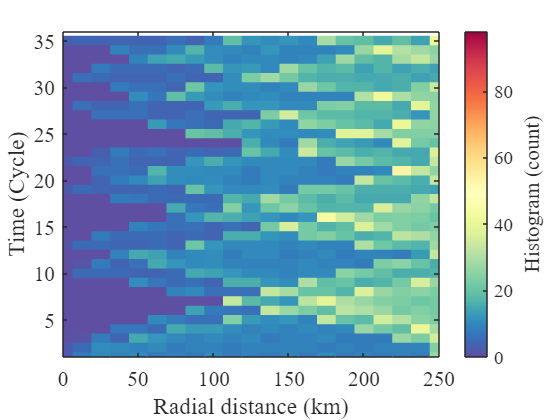

% radialProfile over time
[mz_rt, rmid_rt, tmid_rt, numz_rt, stdz_rt] = radialProfileTime(alongtrack,eddyPath_fun_t);

## Relative vorticity and Streamfunction

[center_zeta,amplitude,radius,core_zeta,shield_zeta] = findEddyCentroid(eddy_field.x, eddy_field.y, eddy_field.ssh,'BoundaryType','zero-zeta','lato',24,'GetBoundary', true,'epsilon',0.01);

% Calculate grid spacing
dx = eddy_field.x(2) - eddy_field.x(1);
dy = eddy_field.y(2) - eddy_field.y(1);
% calculate zeta in (x,y,t) matrix
[zeta] = zetaField(dx,dy,eddy_field.ssh,lato=lato);

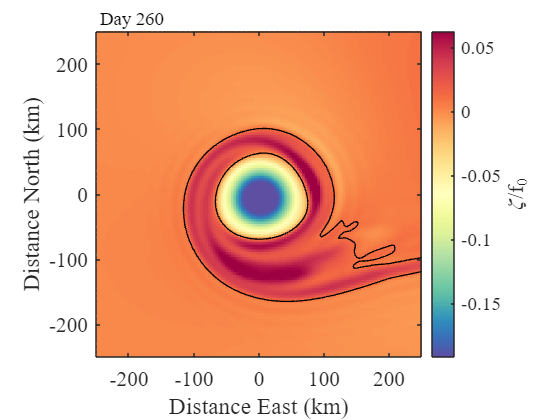

n=260;
zetaContours.core=core_zeta{n};
zetaContours.shield=shield_zeta{n};
plotComposite(eddy_field.x,eddy_field.y,eddy_field.t(n),zeta(:,:,n),eddyPath_fun_t,contour=zetaContours)
hold on
text(-245,270,['Day ',num2str(n)],'FontSize',14,'FontName','times')

## Zeta profile

First zero crossing at r = 70.51 km
Second zero crossing at r = 137.50 km


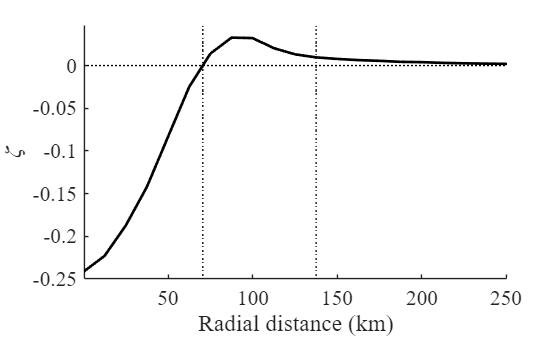

% reshape zeta into an array
fullfield.zeta = reshape(zeta,[],1);

[mz_zeta, rmid] = zetaProfile(fullfield,eddyPath_fun_t);

% streamfunction, energy, enstrophy
% psi=@(x,y,t) (g/fo)*eddy_model
% syms x y t
% u_sym=-diff(psi,y);
% v_sym=diff(psi,x);
% u=@(x,y,t) u_sym;

## Test parameters extraction

%% 
% replace center_xy with centroid of 90% max ssh
% [center_xoyo,amplitude,radius,core_xy] = findEddyCentroid(x, y, ssh,'thresholdratio',0.9,'GetBoundary', true);
plotParameters(alongtrack)

Unrecognized function or variable 'plotParameters'.

## 5. Convergence Rate

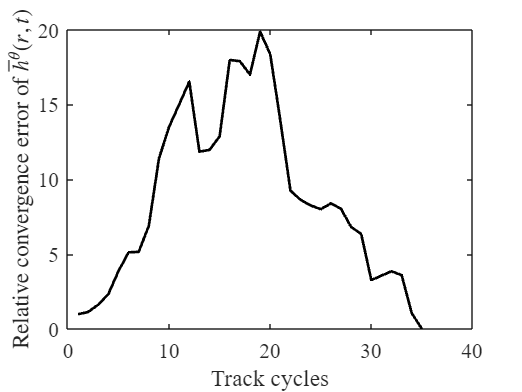

% how many cycles are needed to reach convergence to time-averaged profile
[convergence] = convergenceRate(mz_rt, numz_rt);

## 6. Gaussian fit

%Gaussian fit
eddyFit_fun = @(x,y,t,A,L,x0,y0,cx,cy) A.*exp(-((x-x0-cx*t).^2 + (y-y0-cy*t).^2)/L^2);
% eddyFit_fun = @(x,y,t,A,Lx,Ly,theta,x0,y0,cx,cy) ...
%     A.*exp(-( ((x-x0-cx*t).*cos(theta) + (y-y0-cy*t).*sin(theta)).^2/Lx^2 + ...
%               (-(x-x0-cx*t).*sin(theta) + (y-y0-cy*t).*cos(theta)).^2/Ly^2 ));

[~,amplitude,radius] = findEddyCentroid(eddy_field.x, eddy_field.y, eddy_field.ssh,'thresholdratio',0.9,'GetBoundary', true);
eddyParams.A=amplitude;
eddyParams.L=radius;
eddyParams.xe=eddyPath_fun_t.xe;
eddyParams.ye=eddyPath_fun_t.ye;

trueParams.A=mean(eddyParams.A);
trueParams.L=mean(eddyParams.L);
trueParams.x0=eddyParams.xe(0);
trueParams.y0=eddyParams.ye(0);
trueParams.cx = mean(vdiff(eddyParams.xe(eddy_time),1));
trueParams.cy = mean(vdiff(eddyParams.ye(eddy_time),1));

% new inital parameters for this window
initParams.A = trueParams.A+2*(rand-0.5)*1e-2; %random uncertainty +/- 1e-2
initParams.L = trueParams.L+2*(rand-0.5)*1e3; %random uncertainty +/- 1e3
%assuming you roughly know the eddy center from eddy-tracking algorithm
%beginning of this particular window minus t0 offset of the entire eddy lifetime
% initParams_window.x0 = initParams.x0+i*initParams.cx*max(elapsed_time_window);
% initParams_window.y0 = initParams.y0+i*initParams.cy*max(elapsed_time_window);
initParams.x0 = trueParams.x0+2*(rand-0.5)*10e3; %random uncertainty +/- 10e3
initParams.y0 = trueParams.y0+2*(rand-0.5)*10e3;
initParams.cx = trueParams.cx+2*(rand-0.5)*1e2;  %random uncertainty +/- 1e2
initParams.cy = trueParams.cy+2*(rand-0.5)*1e2;


% initParams.A = true_params.A-0.
% initParams.L = true_params.L+5e3;
% initParams.x0 = true_params.x0-50e3;
% initParams.y0 = true_params.y0+50e3;
% initParams.cx = true_params.cx-0.2e3;
% initParams.cy = true_params.cy+0.2e3;

plot_func = @(xtrans, optimValues, state) plotParamsIteration_ref(xtrans, optimValues, state, [], trueParams);
it_options = optimset('OutputFcn', plot_func,'TolX',1e-3,'TolFun',1e-3);
% Generate bounds
amplitudeTolerance = 0.5;      % ±50% around tracking amplitude
radiusTolerance = 0.5;         % ±50% around tracking radius
positionTolerance = 1.0;       % ±N radii around tracking position
velocityTolerance = 1.0;       % ±N times tracking velocity
tracking_bound_options = struct('amplitudeTolerance', amplitudeTolerance,'radiusTolerance', radiusTolerance, 'positionTolerance', positionTolerance,'velocityTolerance', velocityTolerance);

[LB_tracking, UB_tracking] = generateTrackingBounds(initParams, eddy_time(end), tracking_bound_options);

Tracking-based bounds (window duration: 365.0 days):
  A: [0.065, 0.196] m (tracking: 0.131 m)
  L: [38.9, 116.8] km (tracking: 77.8 km)
  x0: [419.7, 575.3] km (tracking: 497.5 km)
  y0: [-85.0, 70.7] km (tracking: -7.1 km)
  cx: [-6534.664, 0.000] m/s (tracking: -3267.332 m/s)
  cy: [-1017.781, 0.000] m/s (tracking: -508.890 m/s)


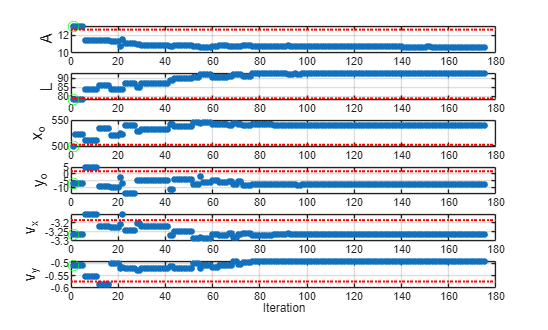

bound.lower=LB_tracking;
bound.upper=UB_tracking;
paramsFit = FitAlongTrackXYToEddyModel(fullfield, eddyFit_fun, initParams, it_options,bound=bound);

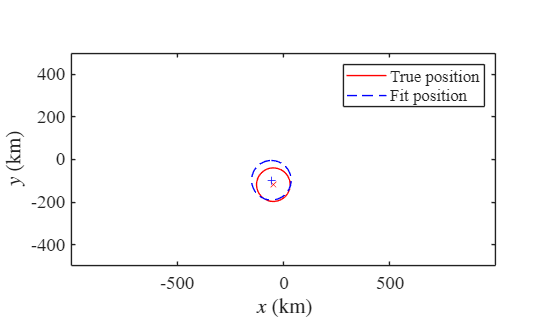

plotFitPosition(eddyPath_fun_t,paramsFit,trueParams)
xlim([min(x/1e3),max(x/1e3)]);ylim([min(y/1e3),max(y/1e3)])

%% time windowed fit
it_options = optimset('TolX',1e-2,'TolFun',1e-2);
[paramsCell, trueParamsCell, window_center] = FitAlongTrackXYToEddyModelWindowed(fullfield, eddyFit_fun, eddyParams, it_options,"window",100,usePreviousFitConstraints=false);

Tracking-based bounds (window duration: 99.0 days):
  A: [0.071, 0.213] m (tracking: 0.142 m)
  L: [68.7, 92.9] km (tracking: 80.8 km)
  x0: [421.2, 582.8] km (tracking: 502.0 km)
  y0: [-78.8, 82.8] km (tracking: 2.0 km)
  cx: [-5372.741, 0.000] m/s (tracking: -2686.371 m/s)
  cy: [-1680.332, 0.000] m/s (tracking: -840.166 m/s)
Using tracking bounds only (first window or previous constraints disabled)
Tracking-based bounds (window duration: 99.0 days):
  A: [0.068, 0.205] m (tracking: 0.137 m)
  L: [71.2, 96.3] km (tracking: 83.8 km)
  x0: [289.2, 456.7] km (tracking: 373.0 km)
  y0: [-114.7, 52.8] km (tracking: -31.0 km)
  cx: [-5612.993, 0.000] m/s (tracking: -2806.496 m/s)
  cy: [-1527.376, 0.000] m/s (tracking: -763.688 m/s)
Using tracking bounds only (first window or previous constraints disabled)
Tracking-based bounds (window duration: 99.0 days):
  A: [0.062, 0.185] m (tracking: 0.124 m)
  L: [74.5, 100.8] km (tracking: 87.7 km)
  x0: [134.6, 310.0] km (tracking: 222.3 km)
  y0

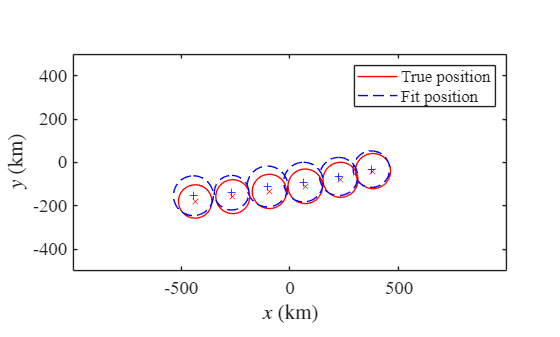

plotFitPosition(eddyPath_fun_t,paramsCell,trueParamsCell)
xlim([min(x/1e3),max(x/1e3)]);ylim([min(y/1e3),max(y/1e3)])

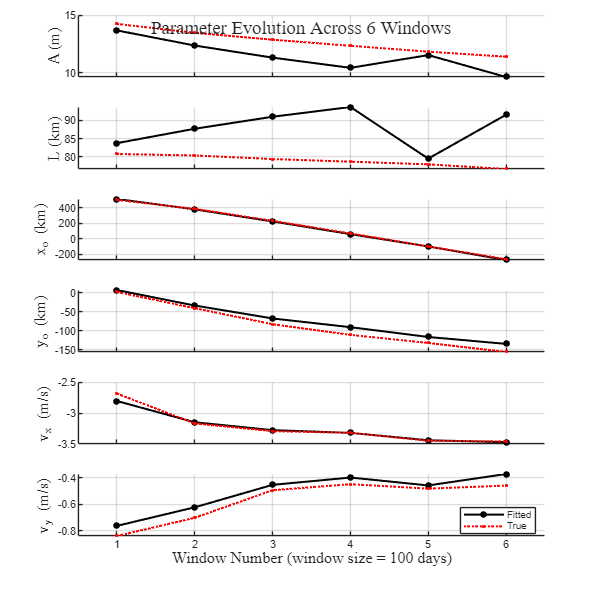

plotFitWindowed(paramsCell,trueParamsCell, eddyPath_fun_t)

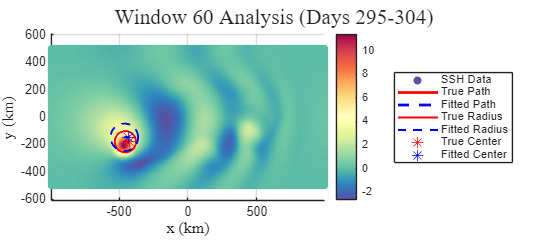

% % To analyze a specific window in detail (e.g., window 3):
 plotSingleWindowFit(fullfield, eddyPath_fun_t, paramsCell, trueParamsCell, 60);